# 02686 - Scientific Computing for Differential Equations - Exam 

## 5 - Classical RK Solver

clear all

% Invariable parameters 
x0 = [1.0;1.0];
N_List = [5000 7500 10000 12500 15000];
abstol_List = [1e-8 1e-7 1e-6 1e-5 1e-4 1e-3];
reltol_List = [1e-8 1e-7 1e-6 1e-5 1e-4 1e-3];
mu_List = [3 20];

% Variable parameters 
mu = mu_List(1);
N = N_List(3);
abstol = abstol_List(2);
reltol = reltol_List(2);

t0 = 0; tf = 50;

% Choose your method
methodList = ["RKFixedSS" "RKAdptativeSS" "ode45" "ode15"];
method = methodList(1)

method = "RKFixedSS"

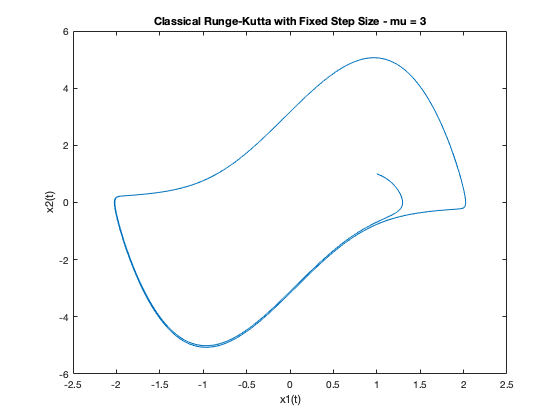


switch method 
    case 'RKFixedSS'
        % Compute the algorithm
        [T,X] = ClassicalRungeKuttaFixedStepSize(@VanDerPol,0,tf,N,x0,mu);
        % Plot the result
        plot(X(:,1),X(:,2))
        xlabel('x1(t)')
        ylabel('x2(t)')
        if (mu == 3)
            t = 'Classical Runge-Kutta with Fixed Step Size - mu = 3';
        end
        if (mu == 20)
            t = 'Classical Runge-Kutta with Fixed Step Size - mu = 20';
        end
        title(t)  
        
    case 'RKAdptativeSS'
        % Compute the algorithm
        [T,X,info] = ClassicalRungeKuttaAdaptativeStep(@VanDerPol,0,tf,x0,N,abstol,reltol,mu);
        % Plot the result
        plot(X(:,1),X(:,2))
        xlabel('x1(t)')
        ylabel('x2(t)')
        if (mu == 3)
            t = 'Classical Runge-Kutta with Adaptative Step Size - mu = 3';
        end
        if (mu == 20)
            t = 'Classical Runge-Kutta with Adaptative Step Size - mu = 20';
        end
        title(t)  
        
    case 'ode45'
        options = odeset('RelTol',reltol,'AbsTol',abstol);
        [T,X]=ode45(@VanDerPol,[0 tf],x0,options,mu);
        % Plot the result
        plot(X(:,1),X(:,2))
        xlabel('x1(t)')
        ylabel('x2(t)')
        if (mu == 3)
            t = 'Solver ode45 - mu = 3';
        end
        if (mu == 20)
            t = 'Solver ode45 - mu = 20';
        end
        title(t) 
        
    case 'ode15s'
        options = odeset('Jacobian',@JacVanDerPol,'RelTol',reltol,'AbsTol',abstol);
        [T,X]=ode15s(@VanDerPol,[0 tf],x0,options,mu);
        % Plot the result
        plot(X(:,1),X(:,2))
        xlabel('x1(t)')
        ylabel('x2(t)')
        if (mu == 3)
            t = 'Solver ode15s - mu = 3';
        end
        if (mu == 20)
            t = 'Solver ode15s - mu = 20';
        end
        title(t)
end

## Question 4

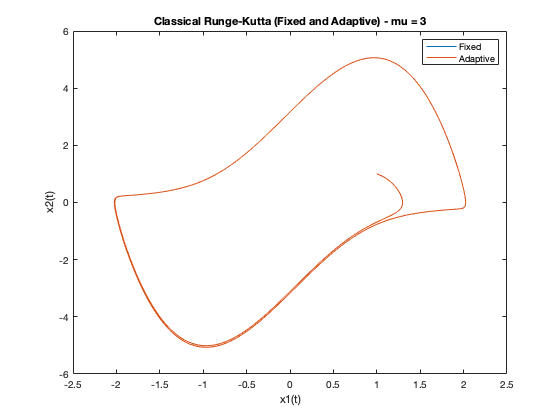

[T,X] = ClassicalRungeKuttaFixedStepSize(@VanDerPol,0,tf,N_List(2),x0,mu_List(1));
plot(X(:,1),X(:,2))
hold on 
[T,X,info] = ClassicalRungeKuttaAdaptativeStep(@VanDerPol,0,tf,x0,N_List(2),abstol,reltol,mu_List(1));
plot(X(:,1),X(:,2))
hold off
xlabel('x1(t)')
ylabel('x2(t)')
title('Classical Runge-Kutta (Fixed and Adaptive) - mu = 3')
legend('Fixed','Adaptive')

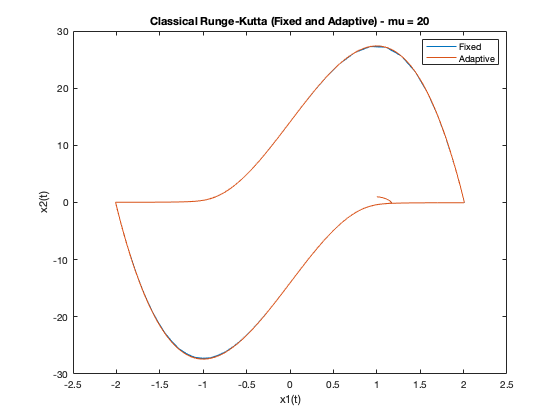

[T,X] = ClassicalRungeKuttaFixedStepSize(@VanDerPol,0,tf,N_List(2),x0,mu_List(2));
plot(X(:,1),X(:,2))
hold on
[T,X,info] = ClassicalRungeKuttaAdaptativeStep(@VanDerPol,0,tf,x0,N_List(2),abstol,reltol,mu_List(2));
plot(X(:,1),X(:,2))
hold off
xlabel('x1(t)')
ylabel('x2(t)')
title('Classical Runge-Kutta (Fixed and Adaptive) - mu = 20')
legend('Fixed','Adaptive')

## Question 5 - Different Comparisons

## Different Step Size

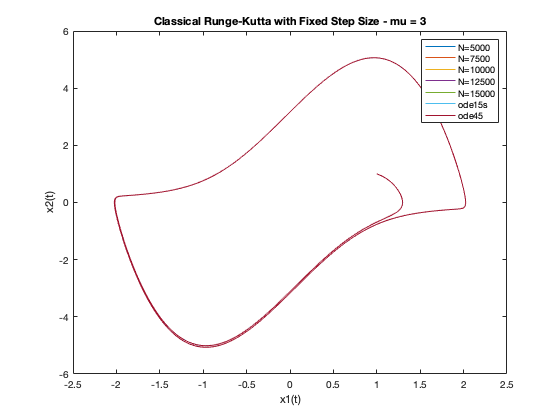

mu = 3;
t0 = 0; tf = 50;
x0 = [1.0;1.0];

for i=1:length(N_List)
    N = N_List(i);
    % Compute the algorithm
    [T,X] = ClassicalRungeKuttaFixedStepSize(@VanDerPol,0,tf,N,x0,mu);
    % Plot the result
    plot(X(:,1),X(:,2))
    hold on
    xlabel('x1(t)')
    ylabel('x2(t)')
    title('Classical Runge-Kutta with Fixed Step Size - mu = 3')
end
options = odeset('Jacobian',@JacVanDerPol,'RelTol',reltol,'AbsTol',abstol);
[T,X]=ode15s(@VanDerPol,[t0 tf],x0,options,mu);
plot(X(:,1),X(:,2))
hold on 
options = odeset('RelTol',reltol,'AbsTol',abstol);
[T,X]=ode45(@VanDerPol,[t0 tf],x0,options,mu);
plot(X(:,1),X(:,2))
hold off

legend('N=5000','N=7500','N=10000','N=12500','N=15000','ode15s','ode45');

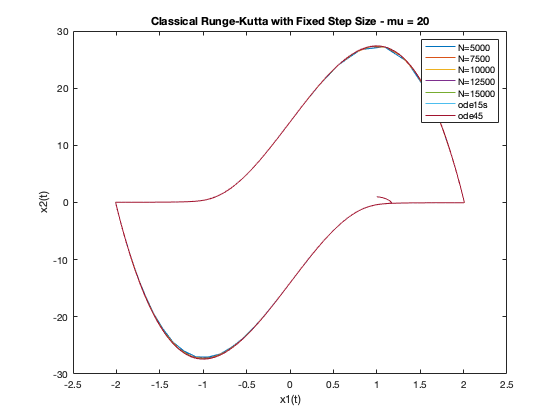

mu = 20;
t0 = 0; tf = 50;
x0 = [1.0;1.0];

for i=1:length(N_List)
    N = N_List(i);
    % Compute the algorithm
    [T,X] = ClassicalRungeKuttaFixedStepSize(@VanDerPol,0,tf,N,x0,mu);
    % Plot the result
    plot(X(:,1),X(:,2))
    hold on
    xlabel('x1(t)')
    ylabel('x2(t)')
    title('Classical Runge-Kutta with Fixed Step Size - mu = 20')
end
options = odeset('Jacobian',@JacVanDerPol,'RelTol',reltol,'AbsTol',abstol);
[T,X]=ode15s(@VanDerPol,[t0 tf],x0,options,mu);
plot(X(:,1),X(:,2))
hold on 
options = odeset('RelTol',reltol,'AbsTol',abstol);
[T,X]=ode45(@VanDerPol,[t0 tf],x0,options,mu);
plot(X(:,1),X(:,2))
hold off

legend('N=5000','N=7500','N=10000','N=12500','N=15000','ode15s','ode45');

## Different Tolerances

N = 4000;
abstol_List = [1e-8 1e-7 1e-6 1e-5 1e-4 1e-3];
reltol_List = [1e-8 1e-7 1e-6 1e-5 1e-4 1e-3];
mu = 3; t0 = 0; tf = 50;
x0 = [1.0;1.0];

reltol = reltol_List(2)

reltol = 1.0000e-07

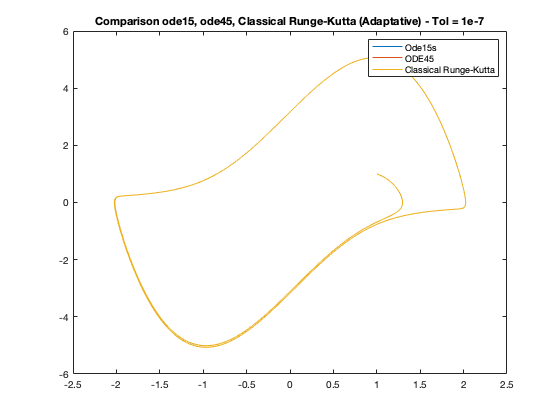

abstol = abstol_List(2);
options = odeset('Jacobian',@JacVanDerPol,'RelTol',reltol,'AbsTol',abstol);
[T,X]=ode15s(@VanDerPol,[0 tf],x0,options,mu);
plot(X(:,1),X(:,2))
hold on 
options = odeset('RelTol',reltol,'AbsTol',abstol);
[T,X]=ode45(@VanDerPol,[0 tf],x0,options,mu);
plot(X(:,1),X(:,2))
hold on
[T,X,info] = ClassicalRungeKuttaAdaptativeStep(@VanDerPol,0,tf,x0,N,abstol,reltol,mu);
plot(X(:,1),X(:,2))
hold off
title('Comparison ode15, ode45, Classical Runge-Kutta (Adaptative) - Tol = 1e-7')
legend('Ode15s','ODE45','Classical Runge-Kutta'); 

reltol = reltol_List(4)

reltol = 1.0000e-05

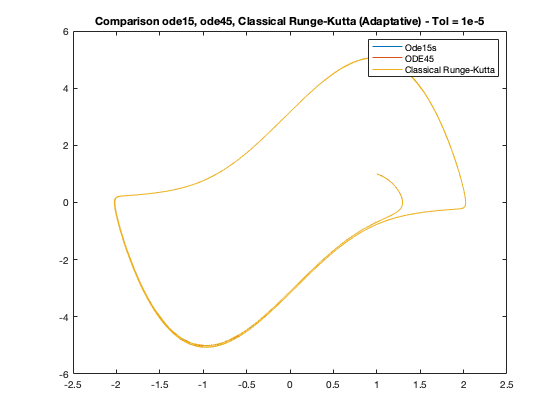

abstol = abstol_List(4);
options = odeset('Jacobian',@JacVanDerPol,'RelTol',reltol,'AbsTol',abstol);
[T,X]=ode15s(@VanDerPol,[0 tf],x0,options,mu);
plot(X(:,1),X(:,2))
hold on 
options = odeset('RelTol',reltol,'AbsTol',abstol);
[T,X]=ode45(@VanDerPol,[0 tf],x0,options,mu);
plot(X(:,1),X(:,2))
hold on
[T,X,info] = ClassicalRungeKuttaAdaptativeStep(@VanDerPol,0,tf,x0,N,abstol,reltol,mu);
plot(X(:,1),X(:,2))
hold off
title('Comparison ode15, ode45, Classical Runge-Kutta (Adaptative) - Tol = 1e-5')
legend('Ode15s','ODE45','Classical Runge-Kutta'); 

reltol = reltol_List(6)

reltol = 1.0000e-03

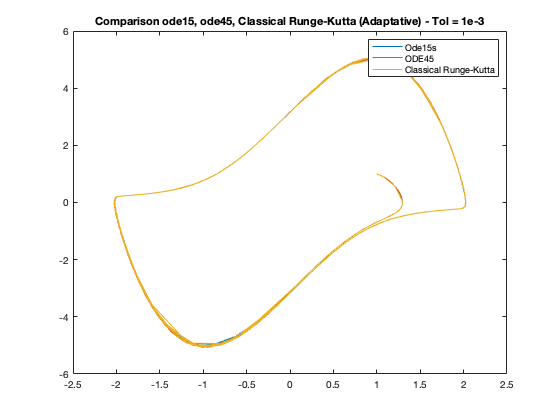

abstol = abstol_List(6);
options = odeset('Jacobian',@JacVanDerPol,'RelTol',reltol,'AbsTol',abstol);
[T,X]=ode15s(@VanDerPol,[0 tf],x0,options,mu);
plot(X(:,1),X(:,2))
hold on 
options = odeset('RelTol',reltol,'AbsTol',abstol);
[T,X]=ode45(@VanDerPol,[0 tf],x0,options,mu);
plot(X(:,1),X(:,2))
hold on
[T,X,info] = ClassicalRungeKuttaAdaptativeStep(@VanDerPol,0,tf,x0,N,abstol,reltol,mu);
plot(X(:,1),X(:,2))
hold off
title('Comparison ode15, ode45, Classical Runge-Kutta (Adaptative) - Tol = 1e-3')
legend('Ode15s','ODE45','Classical Runge-Kutta'); 